## **ProcessMicroplate**

** A Matlab Live-Script Program **

*Version: 3.6, 2024.06.28*

Author: Fred Breidt, USDA/ARS Research Microbiologist, Food Science and Market Quality and Handling Research Unit, 322 Schaub Hall, Box 7624, NC State University, Raleigh, NC 27695-7624

Email: fred.breidt@usda.gov

#### Introduction

While software exists for determining microbial growth kinetics from 96 well microtiter plate optical density data, the accuracy of current methods has been questioned. Variation in derived parameters can occur due to improper background subtraction and failing to consider the impact of initial optical density on the derived parameters (Atolia et al., 2020; Begot et al., 1996). 

#### Background

The MPmodel3 class has the flexibility to allow the user to address these deficiencies and observe the influence initial conditions has on the kinetic parameter output, including:

- Growth rate (GR)

- Lag time (LAG)

- Initial or minimum optical density (MIN)

- Maximum optical density (MAX)

Note that GR, LAG, MIN, and MAX are output table variable names for each of the growth kinetics parameters (see below).

The MPmodel3 class has functions to obtain growth parameters using a sliding window method (Breidt, 1994; Atolia et al., 2020) that is not depending on modeling a sigmoidal shaped curve. The advantage of this approach is that growth parameters can be accurately obtained from oddly shaped growth curves that don’t look like the traditions sigmoidal curve. An additional feature of the MPmodel3 class is that the output parameters can be used to generate a predicted Gompertz curve using a published algorithm (Zewitering et al. 1990).      

*Table 1. Data input format.* This file is easy to generate and required only minor modification (using *Microsoft Excel*) from the original microtiter plate reader output .csv file. The file is saved as a .csv file and then opened using this script (see **Step 1**).  

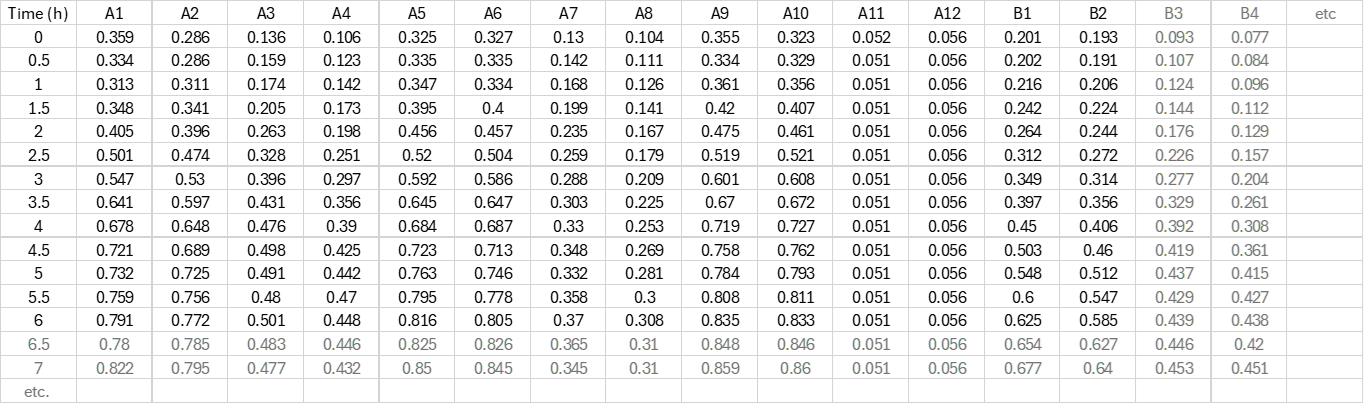

*Table 2. Output data.* Data is output to .csv tables with the text name as entered (see **Step 2**). The output vairable an corresponding standard deviation for duplicates (i.e. for columns 3 and 4 of the example plate data).

Example: EX240513_stats_3_4.csv 

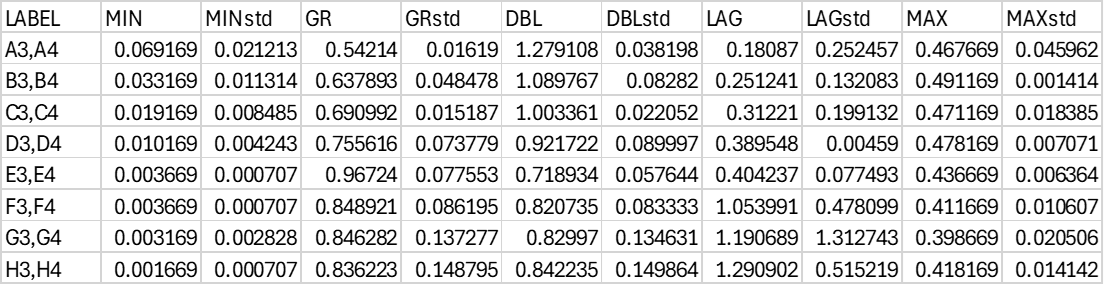 

The output data files may be opened directly in *MS Excel* (as .csv file) for further processing. Graphs may be copied to *Microsoft Word, PowerPoint* or other software using the MS Windows clipboard.   

References: 

- Atolia E, Cesar S, Arjes HA, Rajendram M, Shi H, Knapp BD, Khare S, Aranda-Díaz A, Lenski RE, Huang KC. 2020. Environmental and physiological factors affecting high-throughput measurements of bacterial growth. mBio. 11(5):e01378-20. [https://doi.org/10.1128/mBio.01378-201](https://doi.org/10.1128/mBio.01378-201)

- Begot C, Desnier I, Daudin JD, Labadie JC, Lebert A. 1996. Recommendations for calculating growth parameters by optical density measurements. J Microbiol Meth 25(3):225-232. [https://doi.org/10.1016/0167-7012(95)00090-9](https://doi.org/10.1016/0167-7012(95)00090-9)

- Breidt F, Romick TL, Fleming HP. 1994. A rapid method for the determination of bacterial growth kinetics. J Rapid Methods Autom Microbiol 3(1):59-68. [https://doi.org/10.1111/j.1745-4581.1994.tb00308.x](https://doi.org/10.1111/j.1745-4581.1994.tb00308.x)

- Zwietering MH, Jongenburger I, Rombouts FM, van't Tiet K. 1990. Modeling the bacterial growth curve. Appl Env Microbiol 56(6):1875-1881. [https://doi.org/10.1128/aem.56.6.1875-1881.1990](https://doi.org/10.1128/aem.56.6.1875-1881.1990)

**STEP 1: Open a data file and show microtiter plate**

datafile = "C:\Users\Fred.Breidt\OneDrive - USDA\fbdatafiles\serverWin\matlab\Projects\Misc\MPmodel3\EX240108.csv"   %open a microplate data file

datafile = "C:\Users\Fred.Breidt\OneDrive - USDA\fbdatafiles\serverWin\matlab\Projects\Misc\MPmodel3\EX240108.csv"

*Figure 1. Graph of the microtiter plate optical density data* 

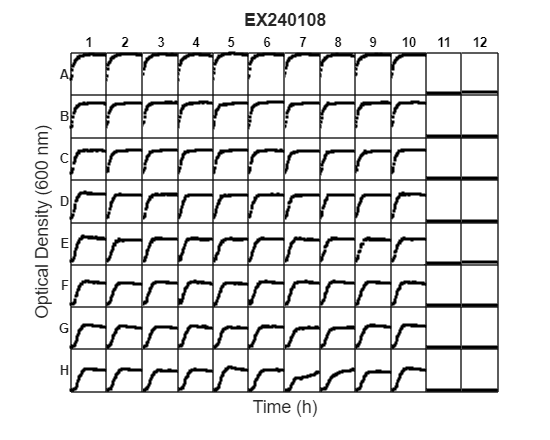

[filepath,fname,~] = fileparts(datafile);
try 
   datatab = readtable(datafile,'VariableNamingRule','preserve');
catch
   msg = "File reading error: please check filename and format" + ... 
      "File format description is in documentation";
   error(msg);
end
model = MPmodel3(datatab,fname);
model.showPlate(); %please wait till plate data is shown below:

nexttile(93)
ylim([0.00 1.08])

%Set row/col vals for blank
%----------------------------------------------------

**STEP 2: Set a file identifier**, to be used for generating an output file. Note that the file will be saved in the current working directory. If a file exists with the same name it will be overwritten. Change the filename before setting the blank and data rows/cols. The output file will have the format: *DataFileName*_*fileID*.csv, where the *DatafileName* is from the original data file (above) and *fileID *is set below:

    fileID = "results";
currentpath = pwd;                  %get current path
statfile = append(model.dataname,"_",fileID,".csv"); %StatsTable name
outputfile = fullfile(currentpath, statfile); %StatsTable path
temppath = outputfile;
if exist(outputfile,'file') == 2
      delete(temppath);
end
outputfile

outputfile = "C:\Users\Fred.Breidt\OneDrive - USDA\fbdatafiles\serverWin\matlab\Projects\Misc\MPmodel3\EX240108_results.csv"

**STEP 3, Set the blank row(s) and col(s).** The mean value from all OD values in the selected row(s) and col(s) will be calculated and used as the blank OD value. The blank OD value will be subtracted from all optical density values for each data point in a growth curve.

blank_rows = "1:8";
blank_cols = "11";
blankrows = getNumberVector(blank_rows);
blankcols = getNumberVector(blank_cols);

**STEP 4, Select the data row(s) and cols(s) and how many data points in a curve to use for the rate calculation. **The optical density data from the growth curves in each row(s) and col(s) will be processed independently to determine: MIN (minimum OD), GR (growth rate), Lag (lag time), and MAX (maximum OD). Results will subsequently be displayed (Table 3) averaging rows or cols for the selected microtiter plate data as determined by **STEP 5**, below.   

 data_rows = "1:8";
 data_cols = "1:5";
datarows = getNumberVector(data_rows);
datacols = getNumberVector(data_cols);
processbyN = 4;

*Figure 2. Histogram of blank values and statistical data*

blankdata = model.setBlankData(blankrows,blankcols)

blankdata = struct with fields:
        XY: [392×2 double]
     Nvals: 392
      mean: 0.0509
    median: 0.0505
      mode: 0.0490
       std: 0.0016


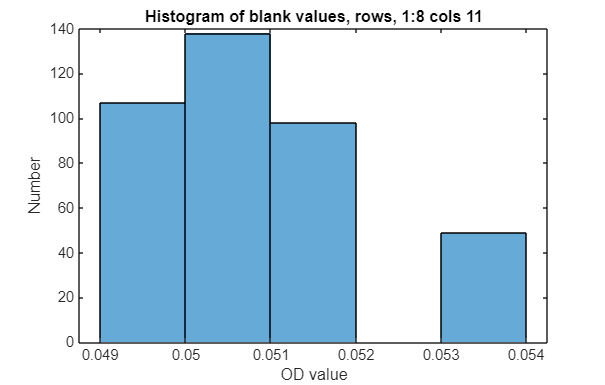

set(gcf, 'NextPlot', 'new'); % next plot goes in new figure
fig = figure(); 
fig.Position(3:4) =[550, 350];
Hh = histogram(blankdata.XY(:,2)); %plot histogram 
hist_titlestr = append('Histogram of blank values, ','rows, ',blank_rows,' cols ',blank_cols );
title(hist_titlestr);
xlabel('OD value');
ylabel('Number');

**Step 5: Generate table of results by row or column. **If reps are in a row across multiple columns, select Row using the drop-down box, otherwise select Column. Note, if the minimum OD after subtraction of the mean blank value is less than the detection limit (machine precision, by default OD = 0.001) it will be displayed as 0. 

rowcol = "Row";

*Table 3. Growth kinetics values for selected (mean) blank values, and data row(s)/cols(s)*

if strcmp(rowcol,'Row') == true
   rowlen = length(datarows);
   for i=1:rowlen
      outfile = model.writeStatsTable(datarows(i),datacols,blankrows, ...
         blankcols, processbyN,fileID);
   end
else
   collen = length(datacols);
   for i=1:collen
      outfile = model.writeStatsTable(datarows,datacols(i),blankrows, ...
         blankcols, processbyN,fileID);
   end
end
outtable = readtable(outfile)

outtable = 8×11 table
          LABEL             MIN        MINstd        GR        GRstd       DBL       DBLstd       LAG       LAGstd       MAX       MAXstd  
    __________________    ________    _________    _______    ________    ______    ________    ________    _______    _______    _________

    {'A1,A2,A3,A4,A5'}     0.37395     0.064403    0.22043     0.04315    3.2755     0.84071    0.042823    0.40778    0.99375     0.011104
    {'B1,B2,B3,B4,B5'}     0.22395     0.026874    0.25042    0.030034    2.8034     0.37129     0.17137       0.29    0.82455     0.006229
    {'C1,C2,C3,C4,C5'}     0.12495     0.01

*Figure 3. Graphs of growth kinetic values:* (MIN, GR, MAX, and LAG) for selected (mean) blank values, and data row(s)/cols(s)  

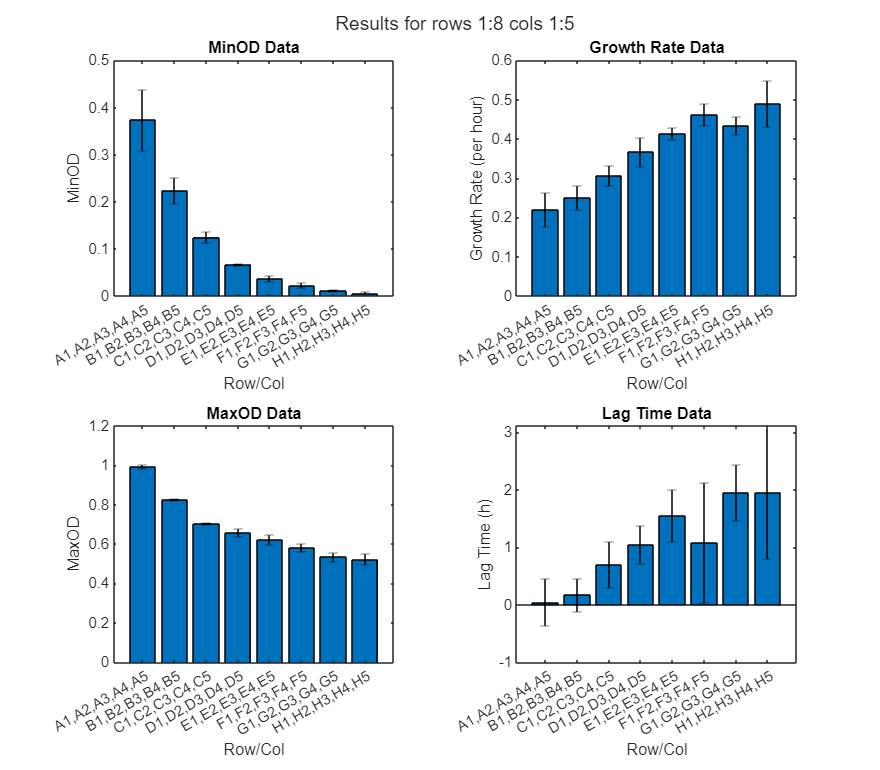

%titlestr = strrep(fileID,'_','-');
titlestr = append('Results for rows ',data_rows,' cols ',data_cols );
fig = figure(); 
fig.Position(3:4) =[800, 700];
plotTableData(outtable,titlestr);

function Th = plotTableData(datatable, titlestring)
%plot the information from the data table
%make 4 plots in a tile layout 
Th = tiledlayout(2,2);
title(Th,char(titlestring));
xvals = categorical(datatable.LABEL);

nexttile
MinODdata = datatable.MIN;
bar(xvals,MinODdata);
title('MinOD Data');
xlabel('Row/Col');
ylabel('MinOD');
hold on;
er = errorbar(xvals, MinODdata, datatable.MINstd);
er.LineStyle = 'none';
er.Color = [ 0 0 0 ];
hold off;

nexttile;
GRdata = datatable.GR;
bar(xvals,GRdata);
title('Growth Rate Data');
xlabel('Row/Col');
ylabel('Growth Rate (per hour)');
hold on;
er = errorbar(xvals, GRdata, datatable.GRstd);
er.LineStyle = 'none';
er.Color = [ 0 0 0 ];
hold off;

nexttile
MaxODdata = datatable.MAX;
bar(xvals,MaxODdata);
title('MaxOD Data');
xlabel('Row/Col');
ylabel('MaxOD');
hold on;
er = errorbar(xvals, MaxODdata, datatable.MAXstd);
er.LineStyle = 'none';
er.Color = [ 0 0 0 ];
hold off;

nexttile
LAGdata = datatable.LAG;
bar(xvals,LAGdata);
title('Lag Time Data');
xlabel('Row/Col');
ylabel('Lag Time (h)');
hold on;
er = errorbar(xvals, LAGdata, datatable.LAGstd);
er.LineStyle = 'none';
er.Color = [ 0 0 0 ];
hold off;
end

function output_vector = getNumberVector(textstring)
%convert a text string such as 1:8 or 5 to a vector 
%"1:8" -> [1 2 3 4 5 6 7 8]
%"5" -> [5]
temp_vector = split(textstring,':');
Nvals = length(temp_vector);
if Nvals == 1 %#ok<ISCL>
   output_vector = str2double(temp_vector);
else
   startval = str2double(temp_vector(1));
   endval = str2double(temp_vector(2));
   veclen = endval - startval + 1;
   output_vector = linspace(startval, endval, veclen);
end %if
end

